This is code to change DSC data into a TS curve for high pressure system

In order for it to work, it needs the csv file from a DSC run using PKSweep since it assumes only 2 complete cycles. There may be trouble if another procedure was used. 

clear;

%This reads the data file, need to change it depending on which test you
%want to analyze
filename='C:\Users\Benjamin\Documents\#Gap Year Post College\Pascal\Work Materials\DSC Data\(C9)2CuBr4 DSC Trace Short.csv'

filename = 'C:\Users\Benjamin\Documents\#Gap Year Post College\Pascal\Work Materials\DSC Data\(C9)2CuBr4 DSC Trace Short.csv'

A=readtable(filename);

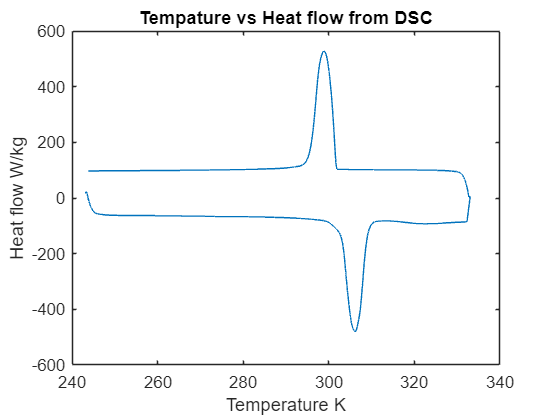

A=A{:,:};
A=A(sum(isnan(A),2)==0,:); %Gets rid of all the NaN rows so that functions later work

temp_data=A(:,2); %C
heat_data=A(:,3); %W/g=J/s*g
time_data=A(:,1); %min, not used except same units are scan rate so need to convert to SI

temp_data=[temp_data(10:end)+273.15]; %K
heat_data=[heat_data(10:end)*1000]; %J/s*kg
time_data=[time_data(10:end)]; 


%Check data looks right
figure()
plot(temp_data,heat_data,'-')
xlabel('Temperature K')
ylabel('Heat flow W/kg')
title('Tempature vs Heat flow from DSC')

% legend('Low Pressure','High Pressure')

%Need to split curves for increasing and decreasing
%This is based on PKSweep since will do two runs

turn1=min(find(temp_data==max(temp_data))) %This is the data point that begins the other direction

turn1 = 10792

turn2=min(find(temp_data==min(temp_data)))

turn2 = 10

turn3=max(find(temp_data==max(temp_data)))

turn3 = 10817

turn4=max(find(temp_data==min(temp_data)))

turn4 = 10

turn5=length(temp_data)

turn5 = 21591

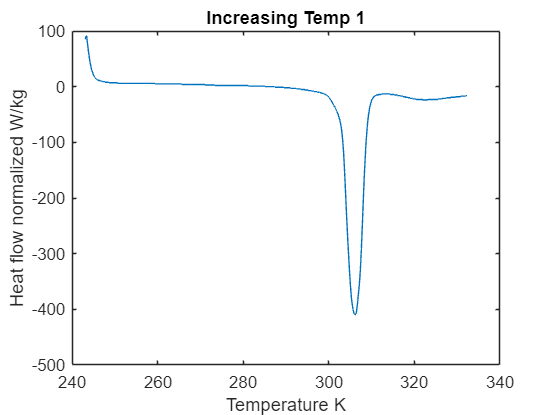



%Might need to switch around the indecies of these arrays in order to get
%something that makes sense physically since Matlab finds things strangly
increase_temp_data_1=double(temp_data(turn2:turn1));
decrease_temp_data_1=double(temp_data(turn1:turn5));
% increase_temp_data_2=single(temp_data(turn4:turn3));
% decrease_temp_data_2=single(temp_data(turn3:turn5));

increase_heat_data_1=double(heat_data(turn2:turn1));
decrease_heat_data_1=double(heat_data(turn1:turn5));
% increase_heat_data_2=single(heat_data(turn4:turn3));
% decrease_heat_data_2=single(heat_data(turn3:turn5));

%Do some background subtraction on heat data
background_heat_increase=prctile(increase_heat_data_1,50);
increase_heat_data_1=increase_heat_data_1-background_heat_increase;
background_heat_decrease=prctile(decrease_heat_data_1,50);
decrease_heat_data_1=decrease_heat_data_1-background_heat_decrease;

%This makes the data all in one matrix
data_increase=cat(2,increase_temp_data_1,increase_heat_data_1);
data_decrease=cat(2,decrease_temp_data_1,decrease_heat_data_1);

diff_increase=cat(1,diff(data_increase(:,1)),[0]);
diff_decrease=cat(1,diff(data_decrease(:,1)),[0]);
data_increase=cat(2,data_increase,diff_increase);
data_decrease=cat(2,data_decrease,diff_decrease);

%This gets rid of all rows with 0 in the temperature difference column
indices = find(data_increase(:,3)==0);
data_increase(indices,:) = [];
indices = find(data_decrease(:,3)==0);
data_decrease(indices,:) = [];
% data_increase=data_increase(all(data_increase,2),:);
% data_decrease=data_decrease(all(data_decrease,2),:);

%This saves memory
clear temp_data
clear heat_data
clear A

%This was to check we split the data into correct arrays
figure()
plot(data_increase(:,1),data_increase(:,2),'-')
xlabel('Temperature K')
ylabel('Heat flow normalized W/kg')
title('Increasing Temp 1')

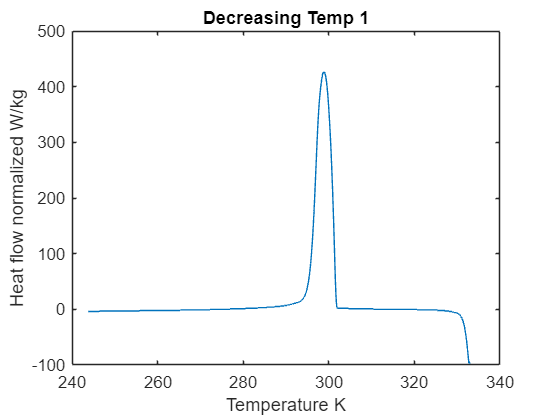

plot(data_decrease(:,1),data_decrease(:,2),'-')
xlabel('Temperature K')
ylabel('Heat flow normalized W/kg')
title('Decreasing Temp 1')

% figure()
% plot(increase_temp_data_2,increase_heat_data_2,'-')
% title('Increasing Temp 2')
% plot(decrease_temp_data_2,decrease_heat_data_2,'--')
% title('Decreasing Temp 2')

This is for testing purposes of DSC data

% temp_data=increase_temp_data_1;
% heat_data=increase_heat_data_1;

%Parameters
Cp=1.21*1000; %This is heat capacity in J/kg K
alpha=6.2*10^(-4); %This is thermal expansivity in K^-1
% rho=0.7739; %kg/L
V=658/1000; %This is specific volume of sample, L/kg
scan_rate=5/60; %This is the scan rate of the DSC machine in K/sec
slope_dTdP=0.237*0.1; %This is the dT/dP curve in K/bar, linear approximation
delta_P=500; %This is the pressure swing in bar
delta_T=slope_dTdP * delta_P; 

%Calculate the entropy of the phase change
% [entropy_data_increase_temp,in_integral,peak_width]=heat_entropy_increasing(data_increase(:,1),data_increase(:,2),scan_rate);
% entropy_data_decrease_temp=heat_entropy_decreasing(data_decrease(:,1),data_decrease(:,2),scan_rate);

%This finds the entropy from phase change with better integration
gap_T=5; %This is the width of integration
[extreme_temp,index_extreme_temp]=max(abs(data_increase(:,2)));
index_Tmid=index_extreme_temp; %Finds the peak temperature
T_mid=data_increase(index_Tmid,1);

T_i=T_mid-gap_T; %This is the lower end of the temperature range
T_f=T_mid+gap_T; %This is the maximum end of the temperature range

index_Ti=min(find(abs(data_increase(:,1)-T_i)<.1));
index_Tf=min(find(abs(data_increase(:,1)-T_f)<.1));
peak_width=abs(index_Tf-index_Ti);

% scan_rate=scan; %This is the scan rate of the DSC machine
heat_flow = zeros(peak_width,1); %This is the argument of the integral
entropy_data = zeros(length(data_increase(:,2)),1); %This is the entropy curve

%First integrate the curve between the T_i and T_f
for i=1:peak_width
    heat_flow(i) = -data_increase(i+index_Ti,2)/(data_increase(i+index_Ti,1) * scan_rate) * data_increase(i+index_Ti,3);
    entropy_data(i+index_Ti)=sum(heat_flow(1:i));
end
last_nonzero=find(entropy_data,1,'last');
entropy_data(last_nonzero:end)=entropy_data(last_nonzero);
data_increase=cat(2,data_increase,entropy_data);


%Now need to shift for high pressure but still use the same temperature
%range
%Need to find how much Temp shift
dT=delta_T;
%Now need to find which index this shifts the entropy curve at high
%pressure to
lower_temp_index=min(find(data_increase(:,4)>0));
upper_temp_index=max(find(data_increase(:,4)<max(data_increase(:,4))));
hold1= data_increase(lower_temp_index,1);
hold2=data_increase(upper_temp_index,1);
shift_lower_temp_index=min(find(data_increase(:,1)>hold1+dT));
shift_upper_temp_index=max(find(data_increase(:,1)<hold2+dT));

%Difference in indecies is because of DSC error
change_lower_index=abs(shift_lower_temp_index-lower_temp_index);
change_upper_index=abs(shift_upper_temp_index-upper_temp_index);
shift=min(change_upper_index,change_lower_index);

%Now shift the entropy data at high pressure by this amount
entropy_data_hp=zeros(length(data_increase(:,4)),1);
for i =1:length(entropy_data_hp)-shift
    entropy_data_hp(i+shift)=data_increase(i,4);
end
data_increase=cat(2,data_increase,entropy_data_hp);






% This finds entropy from phase change with better integration 
% reverse direction

gap_T=5; %This is the width of integration in K
[extreme_temp,index_extreme_temp]=max(abs(data_decrease(:,2)));
index_Tmid=index_extreme_temp; %Finds the peak temperature
T_mid=data_decrease(index_Tmid,1);

T_i=T_mid-gap_T; %This is the lower end of the temperature range
T_f=T_mid+gap_T; %This is the maximum end of the temperature range

index_Ti=min(find(abs(data_decrease(:,1)-T_i)<1));
index_Tf=min(find(abs(data_decrease(:,1)-T_f)<1));
peak_width=abs(index_Tf-index_Ti);

% scan_rate=scan; %This is the scan rate of the DSC machine
heat_flow = zeros(peak_width,1); %This is the argument of the integral
entropy_data = zeros(length(data_decrease(:,2)),1); %This is the entropy curve


%First integrate the curve between the T_i and T_f
for i=1:peak_width
    heat_flow(i) = abs(data_decrease(i+index_Tf,2))/(data_decrease(i+index_Tf,1)* scan_rate) * data_decrease(i+index_Tf,3); %J/g*K^2
    entropy_data(i+index_Tf)=sum(heat_flow(1:i));
end
%This is making the entropy curve a flat line after the peak is done
last_nonzero=find(entropy_data,1,'last');
entropy_data(last_nonzero:end)=entropy_data(last_nonzero);


%Shifts data such that curves match at low temperature region
%Just shifting the cooling curve
shift=min(entropy_data);
entropy_data=entropy_data-shift;

data_decrease=cat(2,data_decrease,entropy_data)

data_decrease =   333.0300  -96.0000   -0.0100   70.4584
  333.0200  -96.0000   -0.0100   70.4584
  333.0100  -95.0000   -0.0100   70.4584
  333.0000  -95.0000   -0.0100   70.4584
  332.9900  -95.0000   -0.0100   70.4584
  332.9800  -95.0000   -0.0100   70.4584
  332.9700  -95.0000   -0.0100   70.4584
  332.9600  -95.0000   -0.0100   70.4584
  332.9500  -95.0000   -0.0100   70.4584
  332.9400  -96.0000   -0.0100   70.4584


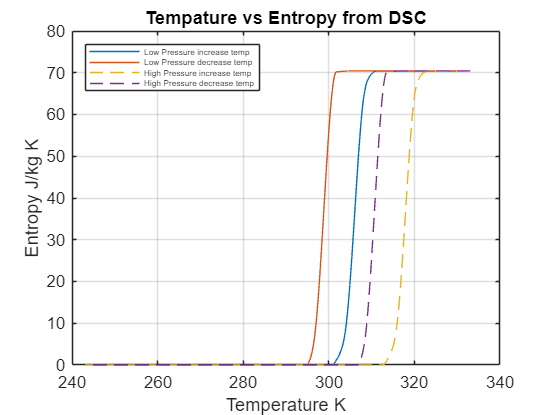



dT=delta_T;
%Now need to find which index this shifts the entropy curve at high
%pressure to
lower_temp_index=max(find(data_decrease(:,4)>0));
upper_temp_index=min(find(data_decrease(:,4)<max(data_decrease(:,4))));
hold1=data_decrease(lower_temp_index,1);
hold2=data_decrease(upper_temp_index,1);
shift_lower_temp_index=max(find(data_decrease(:,1)>hold1+dT));
shift_upper_temp_index=min(find(data_decrease(:,1)<hold2+dT));

%Difference in indecies is because of DSC error
change_lower_index=abs(shift_lower_temp_index-lower_temp_index);
change_upper_index=abs(shift_upper_temp_index-upper_temp_index);
shift=min(change_upper_index,change_lower_index);

%Now shift the entropy data at high pressure by this amount
entropy_data_hp=zeros(length(data_decrease(:,4)),1);
for i =1:length(entropy_data_hp)-shift
    entropy_data_hp(i)=data_decrease(i+shift,4);
end
data_decrease=cat(2,data_decrease,entropy_data_hp);

% new_temp_data_increasing=data_increase(:,1)+delta_T;
% new_temp_data_decreasing=data_decrease(:,1)+delta_T;

figure()
% plot(data_increase(:,1),data_increase(:,4),'-',data_decrease(:,1),data_decrease(:,4),'-')
plot(data_increase(:,1),data_increase(:,4),'-',data_decrease(:,1),data_decrease(:,4),'-',data_increase(:,1),data_increase(:,5),'--',data_decrease(:,1),data_decrease(:,5),'--')
xlabel('Temperature K')
ylabel('Entropy J/kg K')
title('Tempature vs Entropy from DSC')
grid on
legend('Low Pressure increase temp','Low Pressure decrease temp','High Pressure increase temp','High Pressure decrease temp','Location','northwest','Fontsize',5)

Heat capacity correction

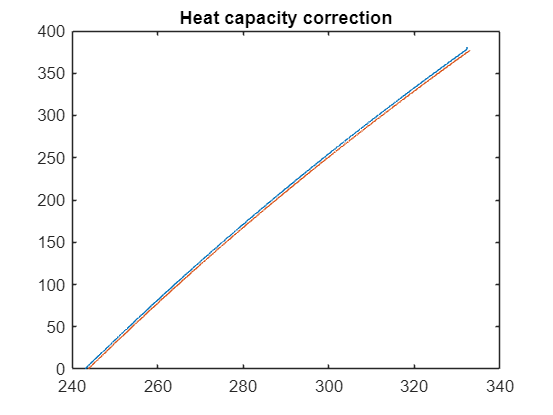

%Calculate heat capacity correction
% [entropy_c_increase,temp_hc_increase]=heat_capacity_entropy_increase(increase_temp_data_1,Cp);
% [entropy_c_decrease,temp_hc_decrease]=heat_capacity_entropy_decrease(decrease_temp_data_1,Cp);


%Heat capacity correction
hc_var=single(zeros(length(data_increase(:,1)),1));
entropy_c=single(zeros(length(data_increase(:,1)),1));


for i=1:length(data_increase(:,1))
    hc_var(i)=Cp/data_increase(i,1) * data_increase(i,3);
    entropy_c(i)=sum(hc_var(1:i));
end
data_increase=cat(2,data_increase,entropy_c);

%Reverse
hc_var=single(zeros(length(data_decrease(:,1)),1));
entropy_c=single(zeros(length(data_decrease(:,1)),1));


for i=length(data_decrease(:,1)):-1:1
    hc_var(i)=Cp/data_decrease(i,1)*data_decrease(i,3);
    entropy_c(i)=abs(sum(hc_var(end:-1:i)));
end
data_decrease=cat(2,data_decrease,entropy_c);

figure()
plot(data_increase(:,1),data_increase(:,6),data_decrease(:,1),data_decrease(:,6))
title('Heat capacity correction')

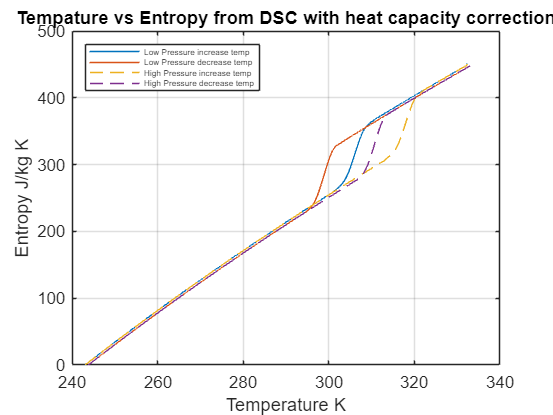

plot(data_increase(:,1),data_increase(:,4)+data_increase(:,6),data_decrease(:,1),data_decrease(:,4)+data_decrease(:,6),   data_increase(:,1),data_increase(:,5)+data_increase(:,6),'--',data_decrease(:,1),data_decrease(:,5)+data_decrease(:,6),'--')
xlabel('Temperature K')
ylabel('Entropy J/kg K')
title('Tempature vs Entropy from DSC with heat capacity correction')
grid on
legend('Low Pressure increase temp','Low Pressure decrease temp','High Pressure increase temp','High Pressure decrease temp','Location','northwest','Fontsize',5)

Now for the thermal compressibility correction

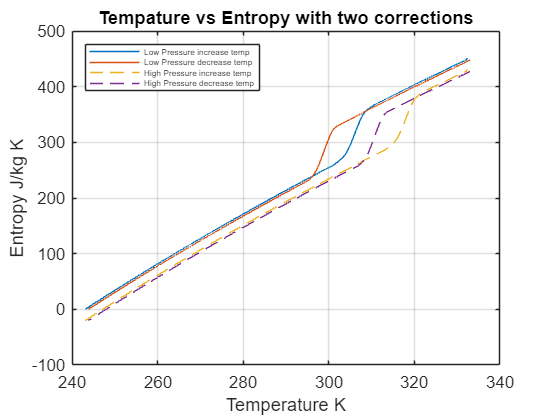

slope_dVdT = V*alpha; %This is the slope of dV/dT

entropy_plus = -delta_P * 10^5*slope_dVdT /1000; %This is the constant shift, needs to be SI units


figure()
plot(data_increase(:,1),data_increase(:,4)+data_increase(:,6),data_decrease(:,1),data_decrease(:,4)+data_decrease(:,6),   data_increase(:,1),data_increase(:,5)+data_increase(:,6)+entropy_plus,'--',data_decrease(:,1),data_decrease(:,5)+data_decrease(:,6)+entropy_plus,'--')
xlabel('Temperature K')
ylabel('Entropy J/kg K')
title('Tempature vs Entropy with two corrections')
grid on
legend('Low Pressure increase temp','Low Pressure decrease temp','High Pressure increase temp','High Pressure decrease temp','Location','northwest','Fontsize',5)

These are functions to calculate entropy from phase change

function [f,g,h] = heat_entropy_increasing(temp_data,heat_data,scan)


gap_T=5; %This is the width of integration
[extreme_temp,index_extreme_temp]=max(abs(heat_data));
index_Tmid=index_extreme_temp; %Finds the peak temperature
T_mid=temp_data(index_Tmid);

T_i=T_mid-gap_T; %This is the lower end of the temperature range
T_f=T_mid+gap_T; %This is the maximum end of the temperature range

index_Ti=min(find(abs(temp_data-T_i)<.1));
index_Tf=min(find(abs(temp_data-T_f)<.1));
peak_width=abs(index_Tf-index_Ti);

scan_rate=scan; %This is the scan rate of the DSC machine
heat_flow = zeros(peak_width,1); %This is the argument of the integral
entropy_data = zeros(length(heat_data),1); %This is the entropy curve

%Number of temperature steps
steps=(T_f-T_i)/(index_Tf-index_Ti);

%Background subtraction
% background_heat=(heat_data(index_Tf)+heat_data(index_Tf))/2
% background_heat=prctile(heat_data,50)
% heat_data=heat_data-background_heat;

%First integrate the curve between the T_i and T_f
for i=1:peak_width
    heat_flow(i) = -heat_data(i+index_Ti)/(temp_data(i+index_Ti) * scan_rate);
    entropy_data(i+index_Ti)=sum(heat_flow(1:i)*steps);
end
last_nonzero=find(entropy_data,1,'last');
entropy_data(last_nonzero:end)=entropy_data(last_nonzero);

f=entropy_data;
g=heat_flow;
h=temp_data(index_Ti:index_Tf-1);
end

%Reverse direction

function f = heat_entropy_decreasing(temp_data,heat_data,scan)

gap_T=5; %This is the width of integration in K
[extreme_temp,index_extreme_temp]=max(abs(heat_data));
index_Tmid=index_extreme_temp; %Finds the peak temperature
T_mid=temp_data(index_Tmid);

T_i=T_mid-gap_T; %This is the lower end of the temperature range
T_f=T_mid+gap_T; %This is the maximum end of the temperature range

index_Ti=min(find(abs(temp_data-T_i)<1));
index_Tf=min(find(abs(temp_data-T_f)<1));
peak_width=abs(index_Tf-index_Ti);

scan_rate=scan; %This is the scan rate of the DSC machine
heat_flow = zeros(peak_width,1); %This is the argument of the integral
entropy_data = zeros(length(heat_data),1); %This is the entropy curve

%Number of temperature steps
steps=(T_f-T_i)/(index_Ti-index_Tf);

%Background subtraction
% background_heat=(heat_data(index_Tf)+heat_data(index_Tf))/2
% background_heat=prctile(heat_data,50)
% heat_data=heat_data-background_heat;

%First integrate the curve between the T_i and T_f
for i=1:peak_width
    heat_flow(i) = -heat_data(i+index_Tf)/(temp_data(i+index_Tf) * scan_rate); %J/g*K^2
    entropy_data(i+index_Tf)=sum(heat_flow(1:i)*steps);
end
%This is making the entropy curve a flat line after the peak is done
last_nonzero=find(entropy_data,1,'last');
entropy_data(last_nonzero:end)=entropy_data(last_nonzero);

%Shifts data such that curves match at low temperature region
%Just shifting the cooling curve
shift=min(entropy_data);
entropy_data=entropy_data-shift;

f=entropy_data;
end


This is to make the high pressure curves, a shifting function

% function f=high_pressure_entropy_increase(entropy_data,temp_data,delta_T)
% %Now need to shift for high pressure but still use the same temperature
% %range
% %Need to find how much Temp shift
% dT=delta_T;
% %Now need to find which index this shifts the entropy curve at high
% %pressure to
% lower_temp_index=min(find(entropy_data>0));
% upper_temp_index=max(find(entropy_data<max(entropy_data)));
% hold1= temp_data(lower_temp_index);
% hold2=temp_data(upper_temp_index);
% shift_lower_temp_index=min(find(temp_data>hold1+dT));
% shift_upper_temp_index=max(find(temp_data<hold2+dT));
% 
% %Difference in indecies is because of DSC error
% change_lower_index=abs(shift_lower_temp_index-lower_temp_index);
% change_upper_index=abs(shift_upper_temp_index-upper_temp_index);
% shift=min(change_upper_index,change_lower_index);
% 
% %Now shift the entropy data at high pressure by this amount
% entropy_data_hp=zeros(length(entropy_data),1);
% for i =1:length(entropy_data_hp)-shift
%     entropy_data_hp(i+shift)=entropy_data(i);
% end
% 
% f=entropy_data_hp;
% end
% 
% 
% 
% %Reverse direction
% 
% function f=high_pressure_entropy_decrease(entropy_data,temp_data,delta_T)
% 
% dT=delta_T;
% %Now need to find which index this shifts the entropy curve at high
% %pressure to
% lower_temp_index=max(find(entropy_data>0));
% upper_temp_index=min(find(entropy_data<max(entropy_data)));
% hold1=temp_data(lower_temp_index);
% hold2=temp_data(upper_temp_index);
% shift_lower_temp_index=max(find(temp_data>hold1+dT));
% shift_upper_temp_index=min(find(temp_data<hold2+dT));
% 
% %Difference in indecies is because of DSC error
% change_lower_index=abs(shift_lower_temp_index-lower_temp_index);
% change_upper_index=abs(shift_upper_temp_index-upper_temp_index);
% shift=min(change_upper_index,change_lower_index);
% 
% %Now shift the entropy data at high pressure by this amount
% entropy_data_hp=zeros(length(entropy_data),1);
% for i =1:length(entropy_data_hp)-shift
%     entropy_data_hp(i)=entropy_data(i+shift);
% end
% 
% f=entropy_data_hp;
% 
% end

These are functions to calculate the heat capacity correction

function [f,g] = heat_capacity_entropy_increase(temp_data,heat_capacity)

Cp=heat_capacity; %This is heat capacity in J/kg K

%Getting equal steps
var1=range(temp_data);
min_T1=min(temp_data);
max_T1=max(temp_data);
var_temp=(min_T1:var1/length(temp_data):max_T1);

%Resizing
var_temp=var_temp(1:end-1);

%Now find the entropy from heat capacity
steps=range(var_temp)/length(var_temp);

hc_var=single(zeros(length(var_temp),1));
entropy_c=single(zeros(length(var_temp),1));



for i=1:length(var_temp)
    hc_var(i)=Cp/var_temp(i);
    entropy_c(i)=sum(hc_var(1:i)*steps);
end

%Zero both curves since noise
%Have to do 10th percentile since DSC noise at turning points
% shift=prctile(entropy_c,10);
% entropy_c=entropy_c-shift;

%Now make the entropy curve for heat capacity correction start at 0 for
%aesthetics
% move=min(entropy_c);
% entropy_c=entropy_c-move;


f=entropy_c;
g=var_temp;
end


%This has backwards direction

function [f,g] = heat_capacity_entropy_decrease(temp_data,heat_capacity)

Cp=heat_capacity; %This is heat capacity in J/kg K

%Getting equal steps
var2=range(temp_data);
min_T2=min(temp_data);
max_T2=max(temp_data);
var_temp=(max_T2:-var2/length(temp_data):min_T2);
%Resizing
var_temp=var_temp(1:end-1);


steps=range(var_temp)/length(var_temp);

hc_var=single(zeros(length(var_temp),1));
entropy_c=single(zeros(length(var_temp),1));


for i=length(var_temp):-1:1
    hc_var(i)=Cp/var_temp(i);
    entropy_c(i)=sum(hc_var(end:-1:i)*steps);
end

%Zero both curves since noise
%Have to do 10th percentile since DSC noise at turning points
% shift=prctile(entropy_c,10);
% entropy_c=entropy_c-shift;

%Now make the entropy curve for heat capacity correction start at 0 for
%aesthetics
% move=min(entropy_c);
% entropy_c=entropy_c-move;

f=entropy_c;
g=var_temp;
end






This is scratch work


%Scratch work
% plot(peak_width,in_integral)
% xlabel('temp K')
% ylabel('stuff in integral')
% var2=zeros(length(peak_width),1);
% var6=zeros(length(peak_width),1);
% steps=diff(peak_width);
% count0=0;
% for i=1:length(steps)
%     if steps(i)==0
%         count0=count0+1;
%     end
% end
% count0
% 1/length(peak_width)
% aver=mean(steps)
% for i=1:length(peak_width)
%     var2(i)=sum(in_integral(1:i)/0.0083);
% end
% max(var2)
% for i=1:length(peak_width)
%     var6(i)=sum(in_integral(1:i)/length(peak_width)*range(peak_width));
% end
% max(var6)
% var3=trapz(in_integral)
% var4=cumtrapz(in_integral);
% max(var4)
% plot(peak_width,var6)
% range(peak_width)/length(peak_width)






% % plot(increase_temp_data_1,entropy_c_increase)
% % plot(increase_temp_data_1,entropy_c_increase,decrease_temp_data_1,entropy_c_decrease)
% % xlabel('temp K')
% % ylabel('entropy from heat capacity')
% % legend('Heating curve','Cooling curve','Location','northwest')
% % steps=range(increase_temp_data_1)/length(increase_temp_data_1)
% % steps=range(decrease_temp_data_1)/length(decrease_temp_data_1)
% 
% var1=range(increase_temp_data_1)
% var2=range(decrease_temp_data_1)
% min_T1=min(increase_temp_data_1)
% min_T2=min(decrease_temp_data_1)
% max_T1=max(increase_temp_data_1)
% max_T2=max(decrease_temp_data_1)
% var3=min(length(increase_heat_data_1),length(decrease_heat_data_1))
% var4=max(length(increase_heat_data_1),length(decrease_heat_data_1))
% var_temp_short=(min_T1:var1/var3:max_T1)
% var_temp_long=(max_T1:-var1/var4:min_T1)
% %Resizing
% var_temp_short=var_temp_short(1:end-1)
% var_temp_long=var_temp_long(1:end-1)
% 
% var5=heat_capacity_entropy_increase(var_temp_short);
% var6=heat_capacity_entropy_decrease(var_temp_long);
% test1=zeros(length(var5),1)+1;
% test2=zeros(length(var6),1)+1.5;
% var7=test1+var5;
% var8=test2+var6;
% 
% figure()
% plot(var_temp_short,var7, var_temp_long,var8,'--')
% title('test1')
% new_entropy_increase=entropy_data_increase_temp+var5;
% new_entropy_decrease=entropy_data_decrease_temp+var6;
% % plot(increase_temp_data_1,entropy_data_increase_temp,var_temp_short,new_entropy_increase)
% plot(increase_temp_data_1,entropy_data_increase_temp,decrease_temp_data_1,entropy_data_decrease_temp,var_temp_short,new_entropy_increase,var_temp_long,new_entropy_decrease)
% xlabel('temp K')
% ylabel('entropy from heat capacity')
% legend('Control','Control','Heating curve','Cooling curve','Location','northwest')
